clear all
%constants
Vo=15

Vo = 15

Vref=2.5

Vref = 2.5000


Rb=10e3

Rb = 10000

R1=((Vo*Rb)/Vref)-Rb

R1 = 50000


D=0.5805

D = 0.5805

n=1.2

n = 1.2000


R = 7.5

R = 7.5000

C = 100e-6

C = 1.0000e-04

L = 2.6195e-5

L = 2.6195e-05


Vkmin=2.5

Vkmin = 2.5000

Ik=2e-3

Ik = 0.0020


Vf=1.05 % We sure about this number; was 1.3 but changed in the report to 1.05 to match slides

Vf = 1.0500

CTR=1

CTR = 1

%Define transfer function

Dp=1-D

Dp = 0.4195

Dpn=Dp/n

Dpn = 0.3496


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.




f2=Dpn*(1-(s*D*L)/(Dpn^2*R))

f2 =
 
  -5.316e-06 s + 0.3204
  ---------------------
         0.9166
 
Continuous-time transfer function.



r2=R/D

r2 = 12.9199


p = @(x,y)1/((1/x)+(1/y));

Gvc=f2*(p(p(r2,R),1/(s*C)))

Gvc =
 
  -5.316e-06 s + 0.3204
  ---------------------
  9.166e-05 s + 0.1932
 
Continuous-time transfer function.





[z, p, k]=zpkdata(Gvc)

z = 1×1 cell array
    {[6.0276e+04]}


p = 1×1 cell array
    {[-2.1073e+03]}


k = -0.0580


2.79e3/(2*pi)

ans = 444.0423

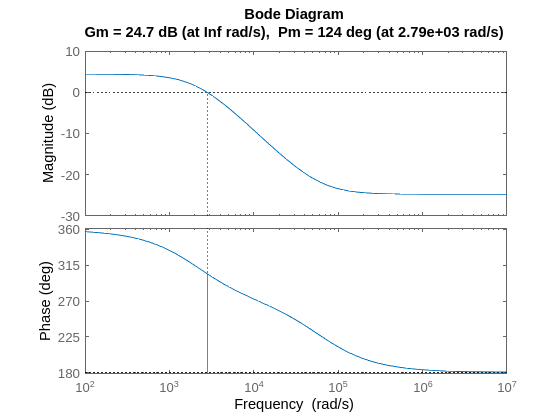


margin(Gvc)

[GM,PM]=margin(Gvc)

GM = 17.2421

PM = 124.3713

% Select crossover frequency

fc = pi*2*5e3

fc = 3.1416e+04

k=20*log10(abs(evalfr(Gvc,i*fc)))

k = -18.0478


kp=10^(-k/20)

kp = 7.9871

kp=1/abs(evalfr(Gvc,i*fc))

kp = 7.9871

%Compontents for feedback

R5=(Vo-Vf-Vkmin)/Ik

R5 = 5.7250e+03


R4=kp*R5/CTR

R4 = 4.5726e+04





C1=1/((fc/5)*R1)

C1 = 3.1831e-09

C3=1/(fc*7*R4)

C3 = 9.9446e-11

99.4e-12

ans = 9.9400e-11


G=(R4*CTR/R5)*(1+s*R1*C1)/(s*R1*C1*(1+s*R4*C3))

G =
 
      0.001271 s + 7.987
  ---------------------------
  7.237e-10 s^2 + 0.0001592 s
 
Continuous-time transfer function.



zpk(G)

ans =
 
  1.7565e06 (s+6283)
  ------------------
    s (s+2.199e05)
 
Continuous-time zero/pole/gain model.



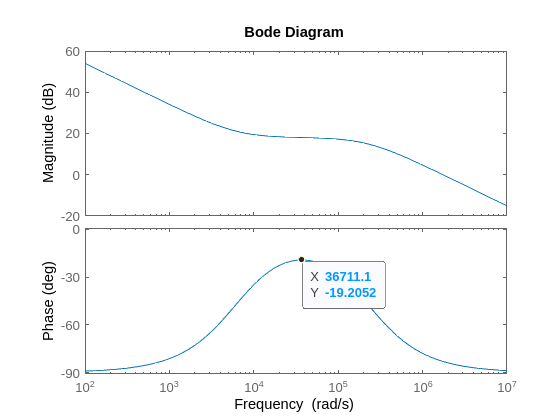


bodeplot(G)

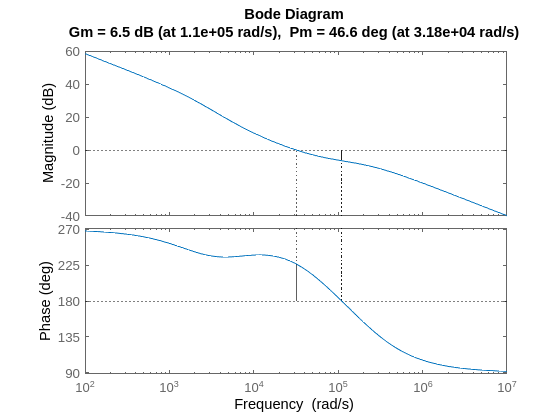

%Loop gain

margin(Gvc*G)

zpk(Gvc*G)

ans =
 
  -1.0187e05 (s-6.028e04) (s+6283)
  --------------------------------
      s (s+2.199e05) (s+2107)
 
Continuous-time zero/pole/gain model.



1.1e5/(2*pi)

ans = 1.7507e+04

3.187e5/(2*pi)

ans = 5.0723e+04